## Proyecto 1 - Probabilidad y estadística

### Nicolas Vargas Flores 1001368855

#### Universidad de Antioquia 2024

datos = readtable("nutrition_elderly.csv");

### Parte 1 - Procedimiento

        **a) ¿Cuál es la población bajo estudio?**

generos = datos.gender == 1; % Esto da como resultado un logical array

hombres = 0;
mujeres = 0;

for i = 1:length(generos)
    if generos(i) == 1
        hombres = hombres + 1;
    else
        mujeres = mujeres + 1;
    end
end

hombres % Total de hombres

hombres = 85

mujeres % Total de mujeres

mujeres = 141

total_muestra = hombres + mujeres

total_muestra = 226


edades = datos.age; % Esto da como resultado un array con las edades
min_edad = min(edades)

min_edad = 65

max_edad = max(edades)

max_edad = 91

La población corresponde a personas adultas mayores entres los 65 y 91 años a los cuales se les hizo un seguimiento nutricional.

       ** b) ¿La anterior información corresponde a una población o a una muestra?**

La anterior información corresponde a una muestra. Específicamente es una muestra de 85 hombres y 141 mujeres para un total de 226 personas mayores involucradas en el estudio.

        **c) ¿Cuántas variables hay en el conjunto de datos?**

variables_cantidad = length(datos.Properties.VariableNames)

variables_cantidad = 13

En este estudio se contemplaron 13 variables diferentes.

        **d)  Realice una tabla con los tipos de características que tiene cada dataset.**

variables = datos.Properties.VariableNames;
tipos = varfun(@class,datos,'OutputFormat','cell');

tabla_tipos = table(variables', tipos', 'VariableNames', {'NombreVariable', 'Tipo'})

tabla_tipos = 13×2 table
       NombreVariable          Tipo   
    ____________________    __________

    {'gender'          }    {'double'}
    {'situation'       }    {'double'}
    {'tea'             }    {'double'}
    {'coffee'          }    {'double'}
    {'height'          }    {'double'}
    {'weight'          }    {'double'}
    {'age'             }    {'double'}
    {'meat'            }    {'double'}
    {'fish'            }    {'double'}
    {'raw_fruit'       }    {'double'}
    {'cooked_fruit_veg'}    {'double'}
    {'chocol'          }    {'double'}
    {'fat'             }    {'double'}


`varfun(@class,datos,'OutputFormat','cell')` aplica la función `class` a cada variable en la tabla `datos` y devuelve los tipos de datos en una celda

Observe que la tabla de los tipos de característica de este dataset son todo datos tipo ***double, ***este tipo de datos hace referencia a los ***double precision*** que son números de alta precisión; numeros flotantes, también conocidos como ***floats*** o decimales

Lo anterior tiene coherencia pues las respuestas de todos los participantes del estudio se almacenaron como números que van del 0 al 5, cantidade (kg, numero de tazas, cm, años) u opciones binarias entre 1 y 2.

### Parte 2 - Análisis descriptivo

-  Realizar las tablas de frecuencia de los datos a los que aplica y elija como presentar  los gráficos más apropiados según el tipo de variable.

Tabla de frecuencias para gender


    1.0000   85.0000   37.6106
    2.0000  141.0000   62.3894



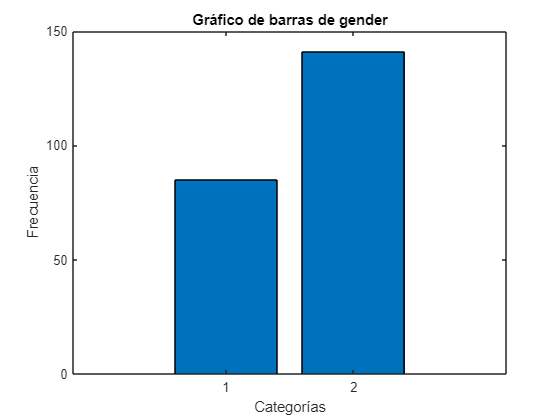

Tabla de frecuencias para situation


    1.0000   98.0000   43.3628
    2.0000  119.0000   52.6549
    3.0000    9.0000    3.9823



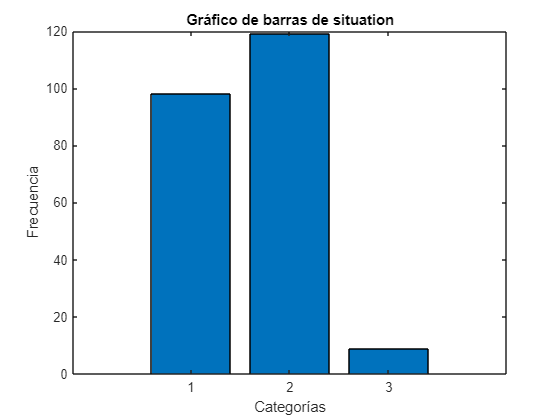

Tabla de frecuencias para tea


     0



    10



    0.7124



     0



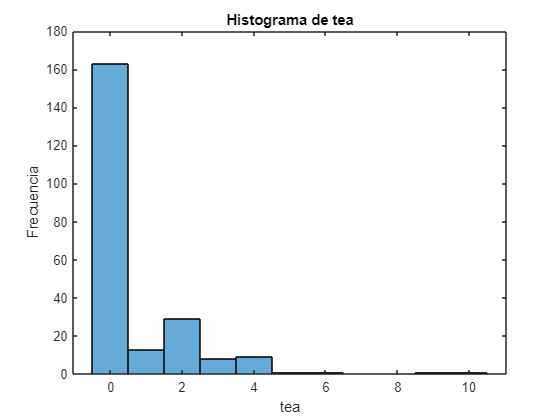

Tabla de frecuencias para coffee


     0



     5



    1.6195



     2



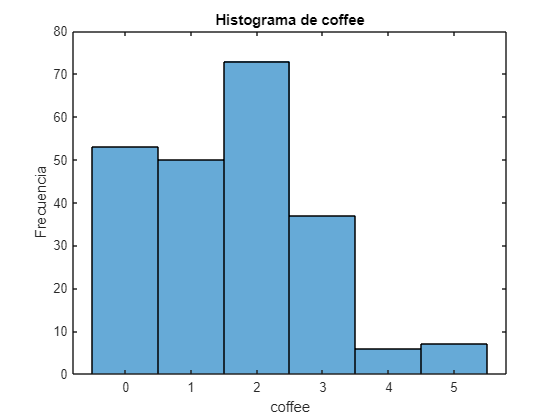

Tabla de frecuencias para height


   140



   188



  163.9602



   163



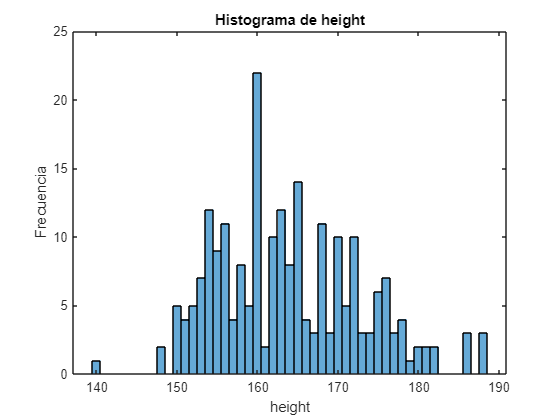

Tabla de frecuencias para weight


    38



    96



   66.4823



    66



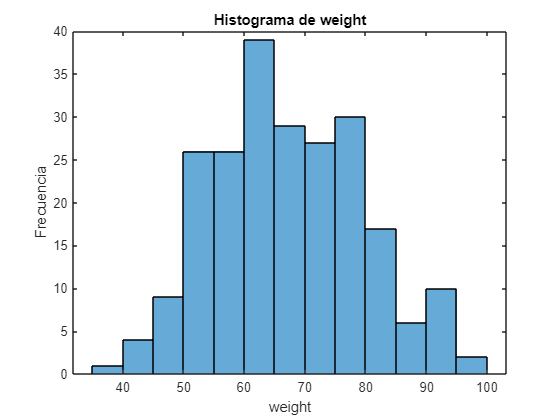

Tabla de frecuencias para age


    65



    91



   74.4779



    74



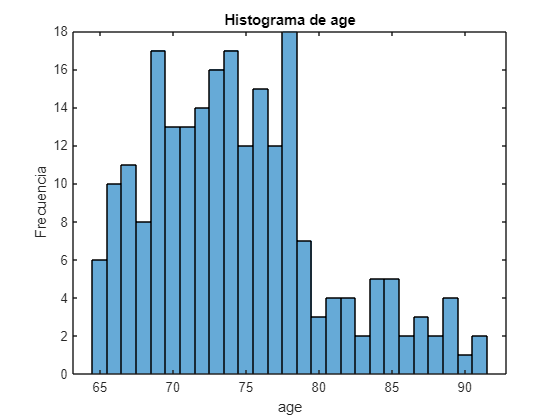

Tabla de frecuencias para meat


         0    1.0000    0.4425
    1.0000    3.0000    1.3274
    2.0000   11.0000    4.8673
    3.0000   83.0000   36.7257
    4.0000   67.0000   29.6460
    5.0000   61.0000   26.9912



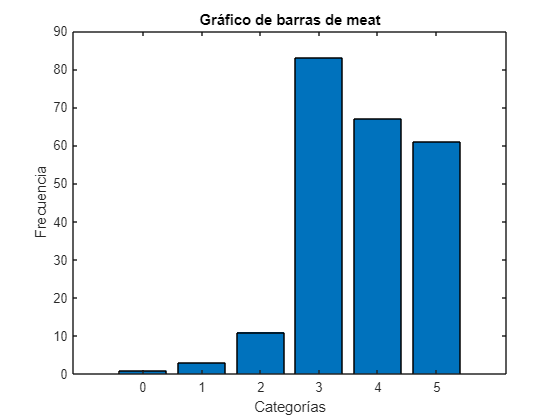

Tabla de frecuencias para fish


         0    4.0000    1.7699
    1.0000   21.0000    9.2920
    2.0000   61.0000   26.9912
    3.0000  118.0000   52.2124
    4.0000   15.0000    6.6372
    5.0000    7.0000    3.0973



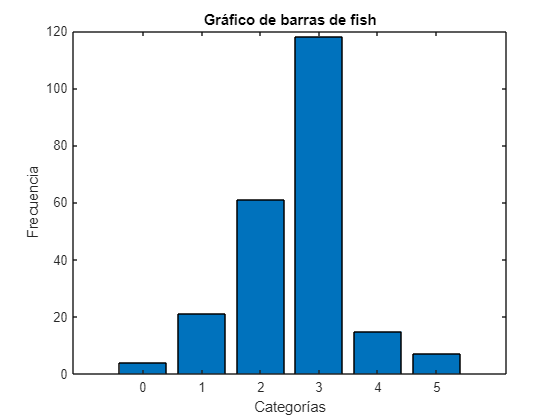

Tabla de frecuencias para raw_fruit


         0    2.0000    0.8850
    1.0000    8.0000    3.5398
    2.0000    8.0000    3.5398
    3.0000   14.0000    6.1947
    4.0000   22.0000    9.7345
    5.0000  172.0000   76.1062



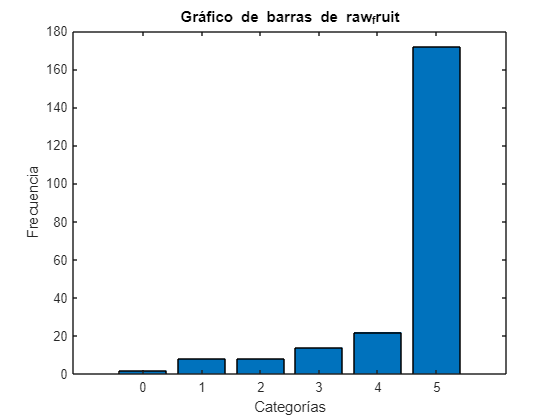

Tabla de frecuencias para cooked_fruit_veg


         0    2.0000    0.8850
    1.0000    3.0000    1.3274
    2.0000    7.0000    3.0973
    3.0000   30.0000   13.2743
    4.0000   36.0000   15.9292
    5.0000  148.0000   65.4867



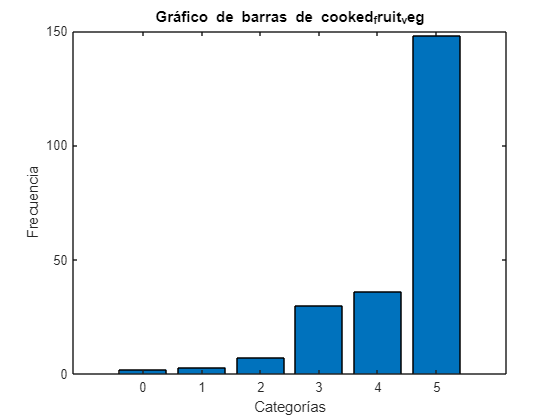

Tabla de frecuencias para chocol


         0   50.0000   22.1239
    1.0000   62.0000   27.4336
    2.0000   16.0000    7.0796
    3.0000   22.0000    9.7345
    4.0000   11.0000    4.8673
    5.0000   65.0000   28.7611



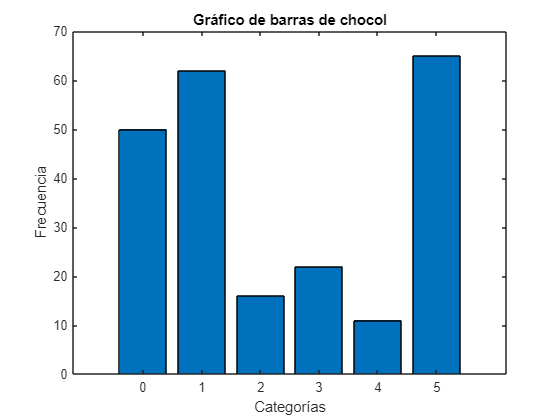

Tabla de frecuencias para fat


    1.0000   15.0000    6.6372
    2.0000   27.0000   11.9469
    3.0000   48.0000   21.2389
    4.0000   68.0000   30.0885
    5.0000   40.0000   17.6991
    6.0000   23.0000   10.1770
    7.0000    1.0000    0.4425
    8.0000    4.0000    1.7699



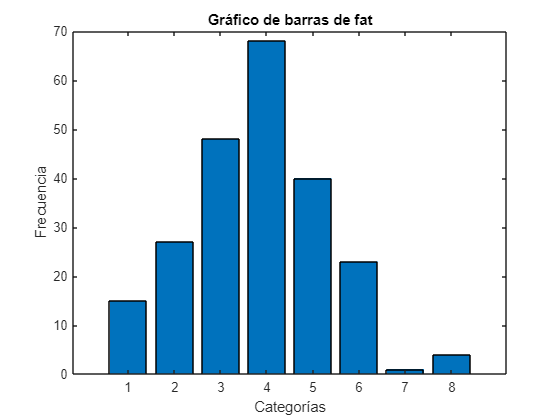

for i = 1:length(variables)
    disp(['Tabla de frecuencias para ', variables{i}])
    if ismember(variables{i}, {'height', 'weight', 'age', 'tea', 'coffee'})
        % Para variables continuas, muestra estadísticas descriptivas y un histograma
        disp(min(datos.(variables{i})));
        disp(max(datos.(variables{i})));
        disp(mean(datos.(variables{i})));
        disp(median(datos.(variables{i})));
        figure; % Crea una nueva figura
        histogram(datos.(variables{i}));
        title(['Histograma de ', variables{i}]); % Agrega un título al gráfico
        xlabel(variables{i}); % Etiqueta el eje x
        ylabel('Frecuencia'); % Etiqueta el eje y
    else
        % Para variables categóricas, muestra una tabla de frecuencias y un gráfico de barras
        tab = tabulate(datos.(variables{i}));
        disp(tab)
        figure; % Crea una nueva figura
        bar(tab(:,2))
        title(['Gráfico de barras de ', variables{i}]); % Agrega un título al gráfico
        xlabel('Categorías'); % Etiqueta el eje x
        ylabel('Frecuencia'); % Etiqueta el eje y
        set(gca, 'XTickLabel',tab(:,1)); % Asigna las etiquetas de las categorías al eje x
    end
end